#  Gasoline Engine Piston Thermal Analysis

This finite element thermal analysis (FEA) examines the heat tolerance for a piston designed for a gasoline engine.

A single domain heat conduction analysis is performed on the piston. 

## Import the geometry

In the cylinder, the piston is exposed to the heat coming from the combustion occurring above the piston top surface and from the cylinder lateral walls that are being cooled down by the cooling system. Here we will create the pde model, import the STL file of the piston, and plot it.

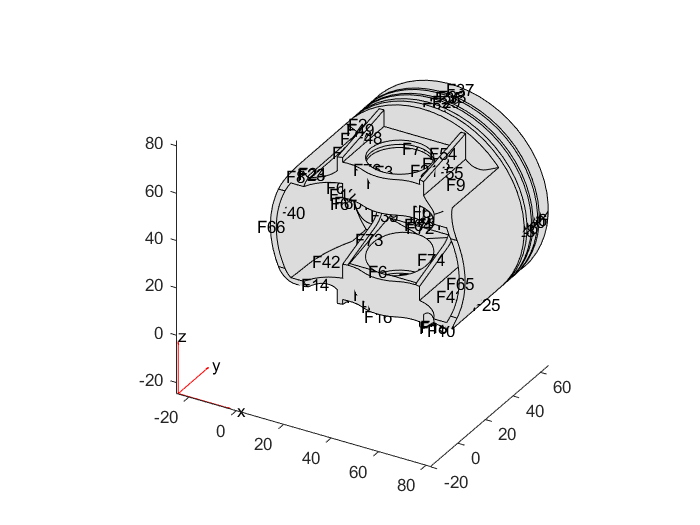

thermalmodel = createpde('thermal','steadystate');
importGeometry(thermalmodel,'Pistone_stl.stl');
pdegplot(thermalmodel, 'FaceAlpha',1, 'FaceLabels', 'on')

## Mesh the Geometry and Determine the Part size                               

From the supplied dimensions above we can estimate the part height should be approximatly 61mm. Create and visualize a tetrahedral mesh of the component with a maximum value of 2 mm.

tic
generateMesh(thermalmodel, 'Hmax', 2);
timeToMesh = toc

timeToMesh = 6.1385

thermalmodel.Mesh

ans =   FEMesh with properties:

             Nodes: [3×213472 double]
          Elements: [10×140138 double]
    MaxElementSize: 2
    MinElementSize: 1
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


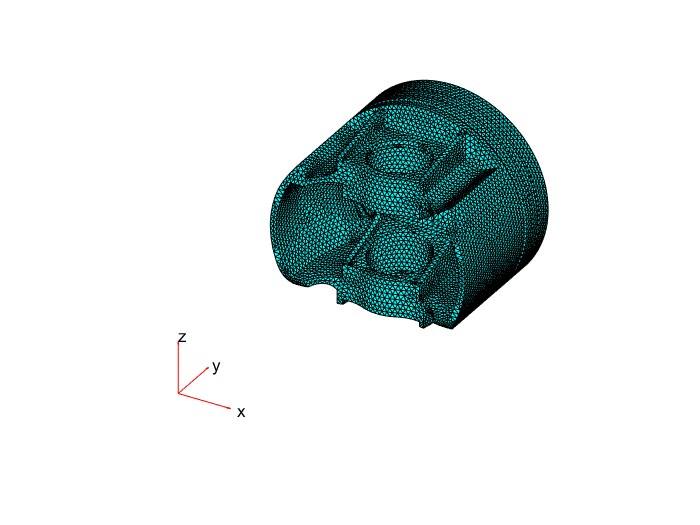

pdemesh(thermalmodel)

Measure the dimensions of the mesh.

xLength = max(thermalmodel.Mesh.Nodes(1,:)) - min(thermalmodel.Mesh.Nodes(1,:))

xLength = 82.2353

yLength = max(thermalmodel.Mesh.Nodes(2,:)) - min(thermalmodel.Mesh.Nodes(2,:))

yLength = 60.8000

zLength = max(thermalmodel.Mesh.Nodes(3,:)) - min(thermalmodel.Mesh.Nodes(3,:))

zLength = 82.2188

## Setup the Material Properties 

The material is assumed to be an aluminum alloy and to have a thermal conductivity of $175\ldotp 728\;\frac{W}{m\;K}$.

tc = 0.175728;

Now remove the units to obtain the value for the thermal properties. 

thermalProperties(thermalmodel,'Cell',1,'ThermalConductivity',tc); 

## Set up the Boundary Conditions

The boundary conditions for this model are taken from a thesis already done on a piston designed for diesel engine operation conditions. If we can find the conditions measures for gasoline engine operating conditions then we should replace the current available data.

Different faces present on the piston are assigned different convection coefficients. The considered surface and there corresponding convection coefficients are:

- **Combustion Zone: **h = 350.6 W/m^2K   ;   T = 638.3 K

- **Top Land: **h = 230 W/m^2K    ;   T = 573 K

- **Rings: **h = 625 W/m^2K ;   T = 345.5 K

- **2nd and 3rd Lands: **h = 115 W/m^2K   ;   T = 345.5

- **Skirt Outisde: **h = 60 W/m^2K  ;   T = 345.5 K

- **Skirt Inside: **h = 162 W/m^2K  ;   T = 383 K

- **Combustion Underside: **h = 608 W/m^2K  ;   T = 383 K

The boundary conditions will be set according to the heat flux. We know that 100% of the heat flux enter from the combustion zone, therefore, the value of the total heat flux = 350.6*638.3 = 223787.98 W/m^2. Then, we know that the rings and the lands have a total heat flux of 30%. Applying the ratios between each convection coefficient (h) and the sum of the convection coefficients of the top land, rings, and other lands, we find that the flux of the top land represents 7% of the total, that of the rings represents 19% of the total, and that of the other lands, 4% of the total. The same procedure is applied for the skirt outside where we need 10% of heat flux. And finally, the same for the combustion underside and skirt inside where the combination must be 53% and by the ratio of the convection coefficients we find that the skirt inside contributes to 11% of the total and the combustion underside contributes to 42%.

h1 = 350.6*1e-6;
T1 = 638.3;
thermalBC(thermalmodel,'Face', 91, 'ConvectionCoefficient', h1, 'AmbientTemperature', T1);
T2 = 573;
h2 = 0.07*T1*h1/T2;
thermalBC(thermalmodel, 'Face', 37, 'ConvectionCoefficient', h2, 'AmbientTemperature', T2);
T3 = 345.5;

T3 = 345.5000

h3 = 0.19*T1*h1/T3;
thermalBC(thermalmodel, 'Face', [27 31 35], 'ConvectionCoefficient', h3, 'AmbientTemperature', T3);
T4 = 345.5;
h4 = 0.04*T1*h1/T4;
thermalBC(thermalmodel, 'Face', [29 33], 'ConvectionCoefficient', h4, 'AmbientTemperature', T4);
T5 = 345.5;
h5 = 0.1*T1*h1/T5;
thermalBC(thermalmodel, 'Face', 25, 'ConvectionCoefficient', h5, 'AmbientTemperature', T5);
T6 = 383;
h6 = 0.11*T1*h1/T6;
thermalBC(thermalmodel, 'Face', [40 46], 'ConvectionCoefficient', h6, 'AmbientTemperature', T6);
T7 = 383;
h7 = 0.42*T1*h1/T7;
thermalBC(thermalmodel, 'Face', [81 87 89], 'ConvectionCoefficient', h7, 'AmbientTemperature', T7);

The bottom face is given a fixed temperature assuming that the rest of the robotic arm acts as a heat sink.

 pdegplot(thermalmodel,'FaceLabels','on', 'FaceAlpha',1)

## Solve the FEA analysis

Solve the model and calculate the max and bulk body temperatures. Time how long the solve takes.

tic
results = solve(thermalmodel);
time = toc

time = 19.0621

## Post-process the Results

Compute the max temperature in $K$ and rewrite that to $C^{\circ }$.

t_max = max(results.Temperature)

t_max = 527.3263

u = symunit;
vpa(rewrite(t_max*u.Kelvin,u.Celsius,'Temperature','absolute'),5)

$$ans = 254.18\,\mathrm{{}^{\circ}C}$$

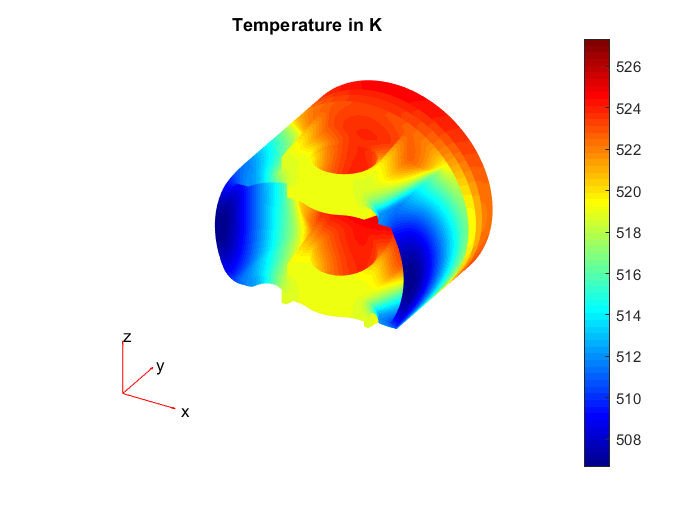

pdeplot3D(thermalmodel,'ColorMapData',results.Temperature)
title('Temperature in K')
colorbar

## Structural Analysis due to Thermal Load

### Create a static structural model.

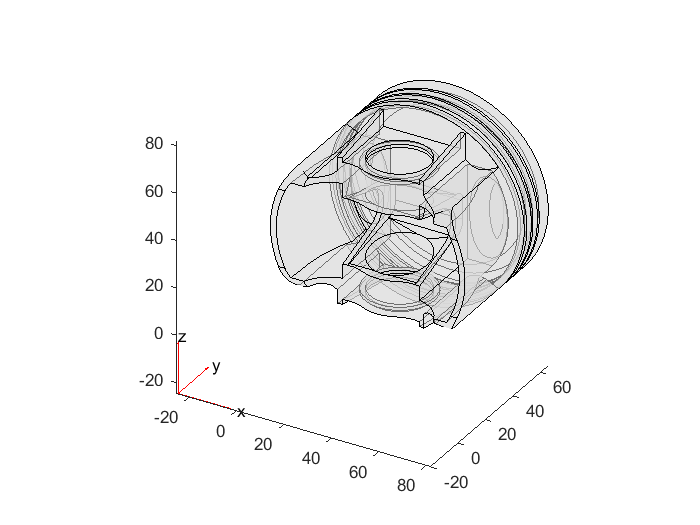

thermalstructuralmodel = createpde('structural', 'static-solid');
importGeometry(thermalstructuralmodel, 'Pistone_stl.stl');
pdegplot(thermalmodel, 'FaceAlpha',0.5)

### Generate Mesh

tic
generateMesh(thermalstructuralmodel, 'Hmax', 2)

ans =   FEMesh with properties:

             Nodes: [3×213472 double]
          Elements: [10×140138 double]
    MaxElementSize: 2
    MinElementSize: 1
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


toc

Elapsed time is 6.112917 seconds.


pdemesh(thermalmodel)

### Setup Material Structural Properties;

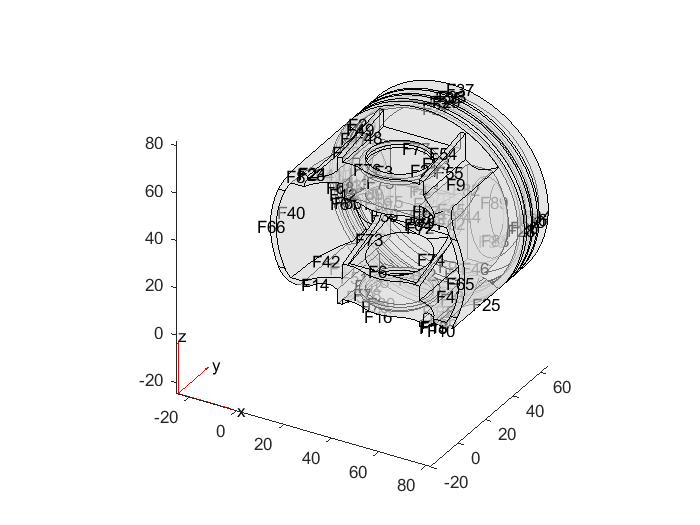

structuralProperties(thermalstructuralmodel, 'Cell', 1, 'YoungsModulus', 67*1e9, 'PoissonsRatio', 0.33, 'CTE', 23*1e-6);
pdegplot(thermalstructuralmodel,'faceLabels','on','FaceAlpha',0.5)

structuralBC(thermalstructuralmodel, 'Face', [2 4], 'Constraint', 'fixed');
structuralBodyLoad(thermalstructuralmodel, 'Temperature', results);
tic
Rts = solve(thermalstructuralmodel);
toc

Elapsed time is 443.303759 seconds.


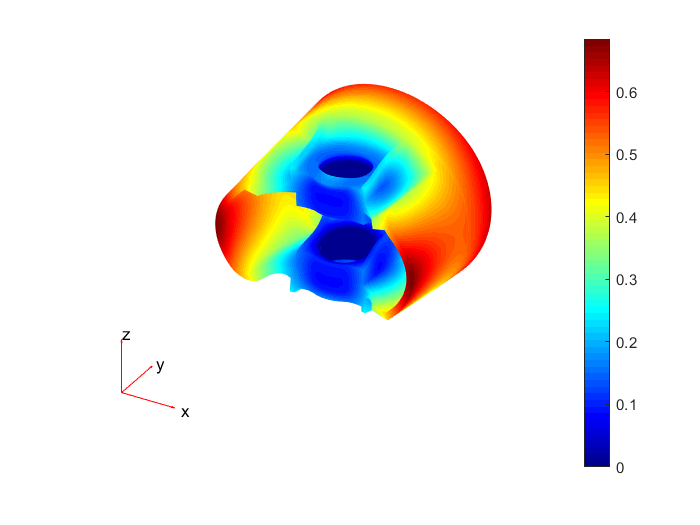

pdeplot3D(thermalstructuralmodel,'ColorMapData',Rts.Displacement.Magnitude, ...
                          'Deformation',Rts.Displacement, ...
                          'DeformationScaleFactor',20)

## Structural Analysis due to Gas Pressure

### Create a static structural model.

structuralmodel = createpde('structural', 'static-solid');
importGeometry(structuralmodel, 'Pistone_stl.stl');
pdegplot(structuralmodel, 'FaceAlpha',0.5)

### Generate Mesh

tic
generateMesh(structuralmodel, 'Hmax', 2)

ans =   FEMesh with properties:

             Nodes: [3×213472 double]
          Elements: [10×140138 double]
    MaxElementSize: 2
    MinElementSize: 1
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


toc

Elapsed time is 5.787748 seconds.


pdemesh(structuralmodel)

### Setup Material Structural Properties

Here we first set all the face to have 0 displacements in lateral directions X and Z and then we fix the face of the pin hole and the other face are symmetric due to the adoption of a quarter model. The load applied is a Surfacetraction force; in other words, pressure applied on the top surface expressed in Pa and on the bottom surfaces we can put the environmental pressure (needs to be discussed).

structuralProperties(structuralmodel, 'Cell', 1, 'YoungsModulus', 67*1e9, 'PoissonsRatio', 0.33, 'CTE', 23*1e-6);
structuralBC(structuralmodel, 'Face', 1:92, 'XDisplacement', 0);
structuralBC(structuralmodel, 'Face', 1:92, 'ZDisplacement', 0);
structuralBC(structuralmodel, 'Face', [2 4], 'Constraint', 'fixed');
structuralBoundaryLoad(structuralmodel, 'Face', [38 91 92], 'Surfacetraction', [0; -16*1e6; 0]);
tic
Rs = solve(structuralmodel);
toc

Elapsed time is 349.539869 seconds.


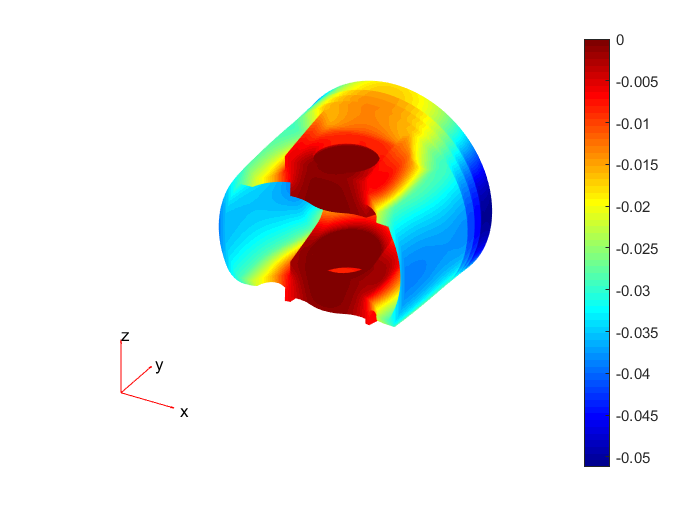

pdeplot3D(structuralmodel,'ColorMapData',Rs.Displacement.uy, ...
                          'Deformation',Rs.Displacement, ...
                          'DeformationScaleFactor',50)

## Thermo-Structural Results

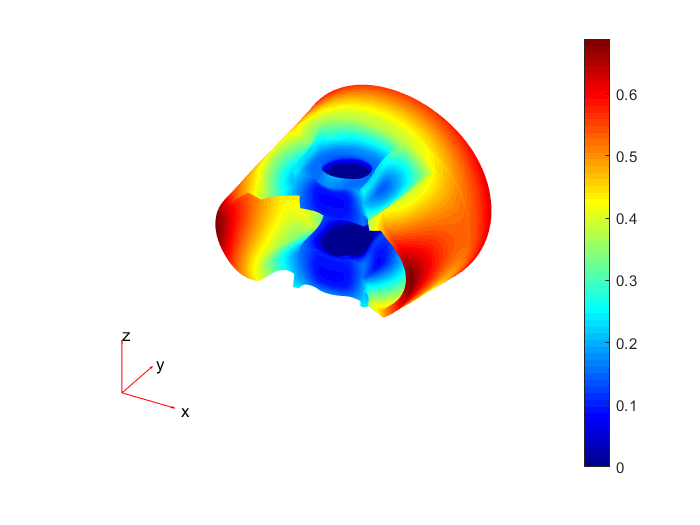

total_results.Displacement.ux = Rs.Displacement.ux + Rts.Displacement.ux;
total_results.Displacement.uy = Rs.Displacement.uy + Rts.Displacement.uy;
total_results.Displacement.uz = Rs.Displacement.uz + Rts.Displacement.uz;
total_results.Displacement.Magnitude = sqrt(total_results.Displacement.ux.^2 + total_results.Displacement.uy.^2 + total_results.Displacement.uz.^2);

pdeplot3D(thermalstructuralmodel,'ColorMapData',total_results.Displacement.Magnitude, ...
                          'Deformation',total_results.Displacement, ...
                          'DeformationScaleFactor',30)

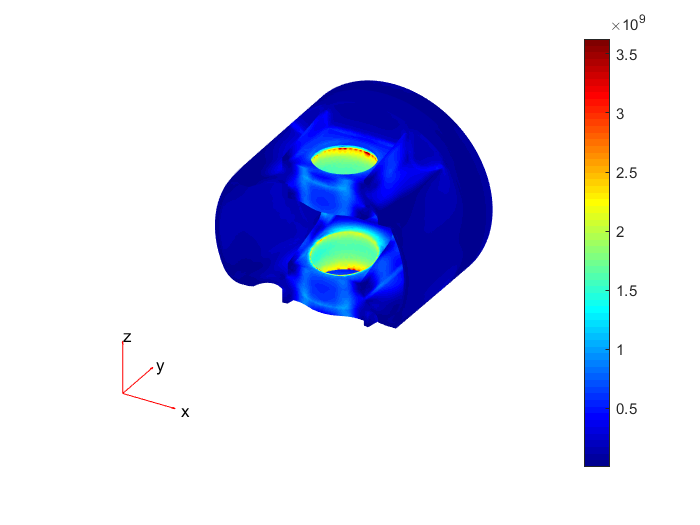

total_results.VonMisesStress = Rs.VonMisesStress + Rts.VonMisesStress;
pdeplot3D(thermalstructuralmodel,'ColorMapData',total_results.VonMisesStress,'Deformation',total_results.Displacement,'DeformationScaleFactor',1)